## Polinomi

### Definizione e valutazione

p = [1 -4 4]; % x^2-4*x+4
v = polyval(p, 2) % = 2^2-4*2+4 = 0

v = 0

p = [4 0 0 -3 2 33]; % 4*x^5-3*x^2+2*x+33
v = polyval(p, 2) % = 4*2^5-3*2^2+2*2+33 = 153

v = 153

X = [2 4 5; -1 0 3; 7 1 5];
V = polyvalm(p, X) % = 4*X^5-3*X^2+2*X+33

V =       154392       78561      193065
       49001       24104       59692
      215378      111419      269614


### Radici

p = [1 -1 -6]; % x^2-x-6
r = roots(p)

r =      3
    -2


p2 = poly(r)

p2 =      1    -1    -6


## Polinomio interpolante: polyfit

### polyfit

% p = polyfit(x,y,n) risolve il sistema lineare V*p=y (p=V\y)
% dove V è la matrice di Vandermonde associata a x

x = linspace(0, 1, 5);
y = 1 ./ (1 + x);
p = polyfit(x, y, 4);
fprintf('y = (%.1f) x^4 + (%.1f) x^3 + (%.1f) x^2 + (%.1f) x + (%.1f)', p(1), p(2), p(3), p(4), p(5));

y = (0.2) x^4 + (-0.5) x^3 + (0.9) x^2 + (-1.0) x + (1.0)

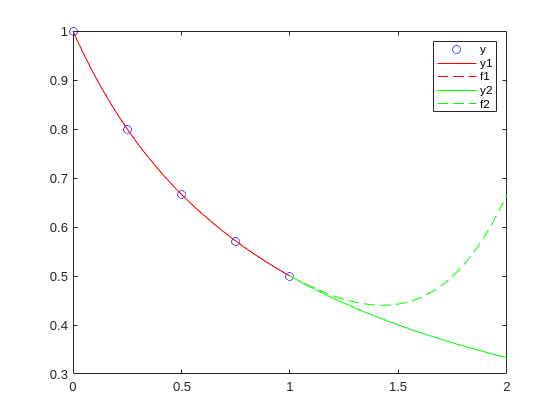

x1 = linspace(0, 1);
y1 = 1 ./ (1 + x1);
f1 = polyval(p, x1);

figure
plot(x, y, 'ob')
hold on
plot(x1, y1, 'r')
plot(x1, f1, 'r--')
legend('y', 'y1', 'f1')

x2 = linspace(1, 2);
y2 = 1 ./ (1 + x2);
f2 = polyval(p, x2);
plot(x2, y2, 'g')
plot(x2, f2, 'g--')
legend('y', 'y1', 'f1', 'y2', 'f2')

### polyfit con shifting & scaling

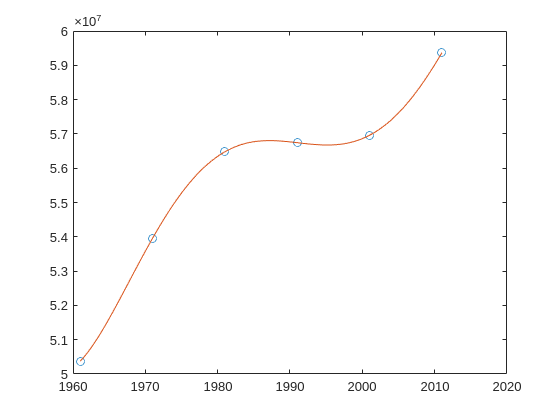

% https://seriestoriche.istat.it/
% Popolazione residente per sesso, nati vivi, morti, saldo naturale, saldo migratorio, saldo totale e tassi di natalità, mortalità, di crescita naturale e migratorio totale - Anni 1862-2014 ai confini attuali

anni = (1961:10:2011)';
popolazione = 1e6*[
    50.374
    53.958
    56.479
    56.744
    56.961
    59.365
    ];
figure
plot(anni,popolazione,'o')

[p,~,mu] = polyfit(anni, popolazione, 5);
x = linspace(anni(1),anni(end));
pv = polyval(p, x, [], mu);

hold on
plot(x,pv)

## Interpolazione di dati: interp1

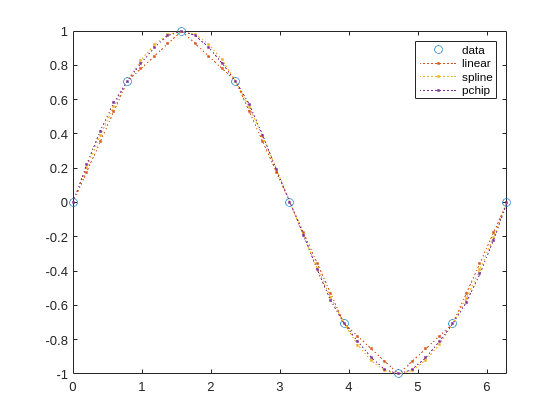

%n = 6;
%x = 2*pi*sort([rand(1,n-2) 0 1]);
%x = [0 1 2.5 3.6 5 7 8.1 10];
x = 0:pi/4:2*pi;
v = sin(x);

figure
plot(x,v,'o');
xlim([0 2*pi]);

%xq = linspace(0,10);
xq = 0:pi/16:2*pi;
vv = sin(xq);

hold on
%plot(xq,vv,'k:')

vq1 = interp1(x,v,xq); % linear
plot(xq,vq1,':.');

vq2 = interp1(x,v,xq,'spline'); % not-a-knot
plot(xq,vq2,':.');

vq3 = interp1(x,v,xq,'pchip'); % shape-preserving piecewise cubic Hermite
plot(xq,vq3,':.');

%vq4 = interp1(x,v,xq,'makima');
%plot(xq,vq4,':.');

legend('data','linear','spline','pchip')

### Confronto tra spline e pchip

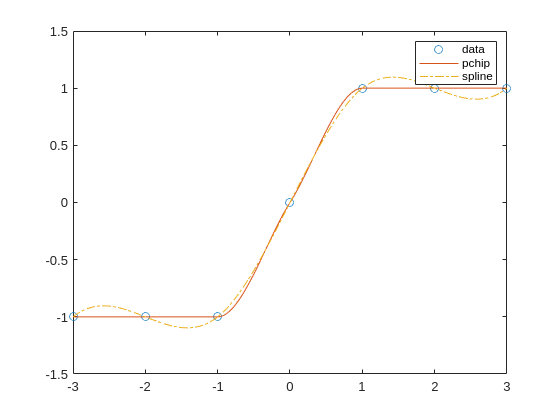

x = -3:3;
y = [-1 -1 -1 0 1 1 1];
xq1 = -3:.01:3;
p = pchip(x,y,xq1);
s = spline(x,y,xq1);
figure
plot(x,y,'o',xq1,p,'-',xq1,s,'-.')
legend('data','pchip','spline')

### Polinomi a tratti

breaks = [0 4 10 15];
coefs = [0 1 -1 1 1; 0 0 1 -2 53; -1 6 1 4 77];
pp = mkpp(breaks,coefs)

pp = struct with fields:
      form: 'pp'
    breaks: [0 4 10 15]
     coefs: [3×5 double]
    pieces: 3
     order: 5
       dim: 1


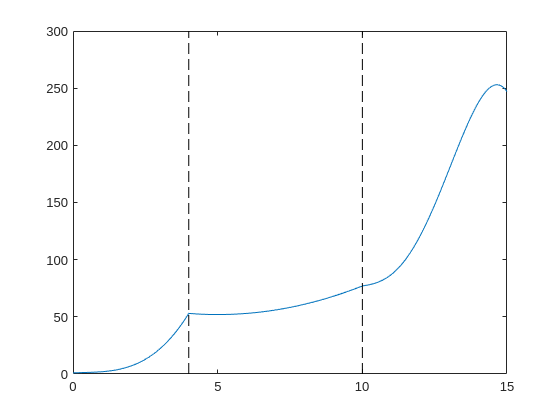

xq = 0:0.01:15;
vv = ppval(pp,xq);

figure
plot(xq,vv)
line([4 4],ylim,'LineStyle','--','Color','k')
line([10 10],ylim,'LineStyle','--','Color','k')

### Polinomi a tratti: pchip

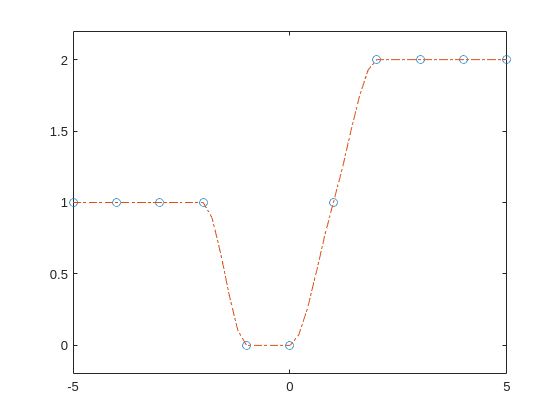

x = -5:5;
y = [1 1 1 1 0 0 1 2 2 2 2];
p = pchip(x,y);

xq = -5:0.2:5;
pp = ppval(p,xq);

figure
plot(x,y,'o',xq,pp,'-.')
ylim([-0.2 2.2])

### Interpolazione di dati: spline vincolate

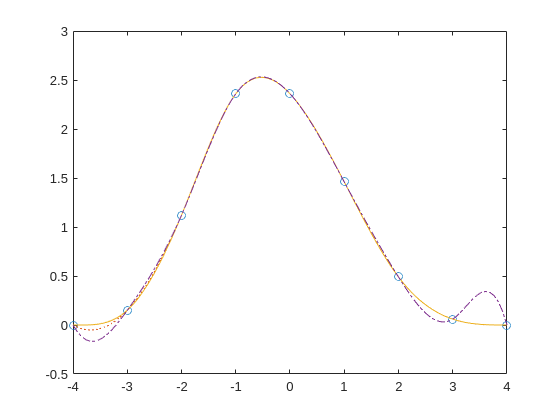

x = -4:4;
y = [0 .15 1.12 2.36 2.36 1.46 .49 .06 0];

s = spline(x,y);
sv1 = spline(x,[0 y 0]);
sv2 = spline(x,[-1 y -2]);

xx = linspace(-4,4,101);

figure
plot(x,y,'o',xx,ppval(s,xx),':',xx,ppval(sv1,xx),'-',xx,ppval(sv2,xx),'-.');

### Riutilizzo dell'interpolante: griddedInterpolant

x = sort(20*rand(100,1));
v = besselj(0,x); % funzione di Bessel del primo tipo

figure
plot(x,v,'ko')

F = griddedInterpolant(x,v)

F =   griddedInterpolant with properties:

            GridVectors: {[100×1 double]}
                 Values: [100×1 double]
                 Method: 'linear'
    ExtrapolationMethod: 'linear'


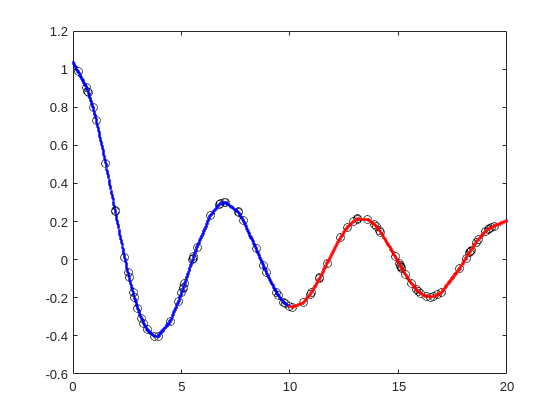

xq = linspace(0,10,500);
vq = F(xq);

hold on
plot(xq,vq,'b.')

xq1 = linspace(10,20,500);
vq1 = F(xq1);
plot(xq1,vq1,'r.')